# ***C. japonicus***** Isolate Growth Code**

#### **Part 1. Find ATP values to corresponding biomass yields & NH3 flux & CUE/NUE**

%----------------------Values to Change for Part 1-----------------------------------


MATmodel = 'Cj_Model.mat';

chitinExRxn = 'EX_cpd11683_e0';
nagExRxn = 'EX_cpd00122_e0';
glcExRxn = 'EX_cpd00027_e0';
CO2ExRxn = 'EX_cpd00011_e0';
NH3ExRxn = 'EX_cpd00013_e0';

mediaRxns = {'EX_cpd00001_e0';'EX_cpd00007_e0';'EX_cpd00009_e0';'EX_cpd00011_e0';'EX_cpd00013_e0';...
    'EX_cpd00030_e0';'EX_cpd00034_e0';'EX_cpd00048_e0';'EX_cpd00058_e0';'EX_cpd00063_e0';...
    'EX_cpd00067_e0';'EX_cpd00099_e0';'EX_cpd00122_e0';'EX_cpd00149_e0';'EX_cpd00205_e0';'EX_cpd00244_e0';...
    'EX_cpd00254_e0';'EX_cpd00635_e0';'EX_cpd00971_e0';'EX_cpd03387_e0';'EX_cpd03396_e0';...
    'EX_cpd10515_e0';'EX_cpd10516_e0';'EX_cpd11574_e0';'EX_cpd11683_e0';'EX_cpd15574_e0'};

biomRxn = 'bio1';

chitinLB = -10;
glcLB = 0;
nagLB = 0;
CO2LB = 0;
mediaLB = -1000;
mediaUB = 1000;
%-------------------------------------------------------------------------

We begin by loading that MATLAB model and finding necessary reactions that may come in handy later. We then find the individual pieces required for constraint-based modeling.

load(MATmodel)

%Carbon source reactions
idxChitinRxn = strcmp(model.rxns,chitinExRxn);
idxNAGRxn = strcmp(model.rxns,nagExRxn);
idxGlcRxn = strcmp(model.rxns,glcExRxn);

%NH3 reaction
idxNH3Rxn = find(strcmp(model.rxns,NH3ExRxn)); %Necessary as we want to see change in NH3 flux

%Biomass reaction
idxBiom = find(strcmp(model.rxns,biomRxn)); %Necessary as we want to see change biomass production


%Fix upper and lower bounds of media -- begine with making all LBs of EX rxns 0 & UBs of EX rxns 1000
    %Then we can readjust the LBs and UBs of media EX rxns only
idxExRxns = find(contains(model.rxns,'EX_'));
model.lb(idxExRxns) = 0;
model.ub(idxExRxns) = 1000;

for i = 1:length(mediaRxns)
    idxMediaRxn = find(strcmp(model.rxns,mediaRxns(i)));
    model.lb(idxMediaRxn) = mediaLB;
    model.ub(idxMediaRxn) = mediaUB;
end

%Make sure CO2 remains 0 (just to be sure)
idxCO2Rxn = find(strcmp(model.rxns,CO2ExRxn));
model.lb(idxCO2Rxn) = 0;

%Time to find CUE & NUE
%To begin, we need to find all indeces related to exchange, sinks, drains, etc
[~, colIdcs] = find(model.S~=0);
[counts, bins] = hist(colIdcs,1:size(model.S,2)); %#ok<*HIST> 
exIdx = bins(counts==1);

cTerms = model.rxns(exIdx);
nTerms = model.rxns(exIdx);

cTerms2 = model.rxns(exIdx);
nTerms2 = model.rxns(exIdx);

%Next, of these reactions, we find the related metabolite and information regarding the number of carbon & nitrogen molecules
metIdx = zeros(length(exIdx),1);
cVal = zeros(length(exIdx),1);
nVal = zeros(length(exIdx),1);

for k = 1:length(exIdx)
    metIdx(k) = find(model.S(:,exIdx(k))~=0); %Indeces of metabolites
    
    % Carbon Info:
    if contains(model.metFormulas(metIdx(k)),'C')
        if strlength(model.metFormulas(metIdx(k))) >= 3
            if ~isnan(str2double(extract(model.metFormulas(metIdx(k)),2)))
                if ~isnan(str2double(extract(model.metFormulas(metIdx(k)),3)))
                    cVal(k) = str2double(append(extract(model.metFormulas(metIdx(k)),2),extract(model.metFormulas(metIdx(k)),3)));
                elseif isnan(str2double(extract(model.metFormulas(metIdx(k)),3)))
                    cVal(k) = str2double(extract(model.metFormulas(metIdx(k)),2));
                end
            elseif isnan(str2double(extract(model.metFormulas(metIdx(k)),2)))
                cVal(k) = 1;
            end
        end
    end
    
    %Nitrogen Info:
    if contains(model.metFormulas(metIdx(k)),'N')
        if strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) >= 2
            if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)))
                    nVal(k) = str2double(append(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)));
                elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)))
                    nVal(k) = str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1));
                end
            elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                nVal(k) = 1;
            end
        elseif strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) == 0
            nVal(k) = 1;
        elseif strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) == 1
            if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                nVal(k) = str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1));
            elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                if cell2mat(isstrprop(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),'upper')) == 1
                    nVal(k) = 1;
                elseif cell2mat(isstrprop(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),'lower')) == 0
                    nVal(k) = 0;
                end         
            end
        end
    end
end

cTerms(cVal==0) = [];
nTerms(nVal==0) = [];

cTerms2(cVal==0) = [];
nTerms2(nVal==0) = [];

%To avoid expanding loops, make all-zeros columns that we can add values where necessary
biomassValsCJ = zeros(3001,1);
NH3ValsCJ = zeros(3001,1);

CUEvalsCJ = zeros(3001,1);
NUEvalsCJ = zeros(3001,1);
TERvalsCJ = zeros(3001,1);

CUEcheck = zeros(2001,1);
NUEcheck = zeros(2001,1);

cFluxCJ = zeros(length(cTerms),3001);
nFluxCJ = zeros(length(nTerms),3001);

Time to begin the loop performing FBA & pFBA for multiple values of ATP. We'll pull out the biomass value, NH3 flux, CUE & NUE.

% Get ATP terms for CH rxn
CHrxn = find(strcmp(model.rxns,'ChitinHydrolysis_e0'));

for i = 0:0.01:30

    %Equality reactions--coefficients & rhs
    Aeq = model.S;
    beq = zeros(size(Aeq,1),1);
    
    %Changing terms!!
    Aeq(4,CHrxn) = i; %H+ term
    Aeq(6,CHrxn) = -i; %ATP term
    Aeq(9,CHrxn) = i; %ADP term
    Aeq(10,CHrxn) = i; %Phosphate term
    Aeq(36,CHrxn) = -i; %H2O term

    %Update LBs and UBs
    Aeqlb = model.lb;
    Aeqlb(idxChitinRxn) = chitinLB;
    Aeqlb(idxNAGRxn) = nagLB;
    Aeqlb(idxGlcRxn) = glcLB;
    
    Aequb = model.ub;
    
    %Inequality reactions -- empty sets
    Aineq = []; bineq = [];
    
    %Build Gurobi model using all above data;        
    model.A = sparse([Aineq; Aeq]);
    model.rhs = [bineq; beq];
    model.lb = Aeqlb;
    model.ub = Aequb;
    model.sense = [repmat('<',1,size(Aineq,1)) repmat('=',1,size(Aeq,1))];
    
    f = zeros(1,size(Aeq,2));
    f(idxBiom) = 1;
    
    model.obj = f;
    model.modelsense = 'max';
    params.outputflag = 0;
    result = gurobi(model,params); 
    
    j = round(100*i + 1); %Take the i value and make it whole numbers starting at 1
    biomassValsCJ(j) = result.objval/10; %Biomass yield necessary for figure
    
    %Now we perform pFBA by constraining the result.objval (biomass) and minimizing total flux
    if contains(result.status,'OPTIMAL')

        [m,n] = size(model.S);
        IrrevPosRxns = zeros(n,1);
        IrrevNegRxns = zeros(n,1);
        RevRxns = zeros(n,1);
        
        for k = 1:n
            if Aeqlb(k) < 0 && Aequb(k) > 0
                RevRxns(k) = 1;
            elseif Aeqlb(k) < 0 && Aequb(k) == 0
                IrrevNegRxns(k) = 1;
            elseif Aeqlb(k) == 0 && Aequb(k) > 0
                IrrevPosRxns(k) = 1;
            end
        end
        
        pAineqPRxns1 = zeros(n,2*n);
        pAineqPRxns2 = zeros(n,2*n);
        for l = 1:n    
            if IrrevPosRxns(l) == 1
                pAineqPRxns1(l,l) = -1;
                pAineqPRxns2(l,l) = 1;
                pAineqPRxns2(l,n+l) = -1;
            end
        end
        pAineqPRxns1 = pAineqPRxns1(any(pAineqPRxns1,2),:);
        pAineqPRxns2 = pAineqPRxns2(any(pAineqPRxns2,2),:);
        
        pAineqNRxns1 = zeros(n,2*n);
        pAineqNRxns2 = zeros(n,2*n);
        for l = 1:n    
            if IrrevNegRxns(l) == 1
                pAineqNRxns1(l,l) = 1;
                pAineqNRxns2(l,l) = -1;
                pAineqNRxns2(l,n+l) = -1;
            end
        end
        pAineqNRxns1 = pAineqNRxns1(any(pAineqNRxns1,2),:);
        pAineqNRxns2 = pAineqNRxns2(any(pAineqNRxns2,2),:);
        
        pAineqRRxns1 = zeros(n,2*n);
        pAineqRRxns2 = zeros(n,2*n);
        for l = 1:n    
            if RevRxns(l) == 1
                pAineqRRxns1(l,l) = -1;
                pAineqRRxns1(l,n+l) = -1;
                pAineqRRxns2(l,l) = 1;
                pAineqRRxns2(l,n+l) = -1;
            end
        end
        pAineqRRxns1 = pAineqRRxns1(any(pAineqRRxns1,2),:);
        pAineqRRxns2 = pAineqRRxns2(any(pAineqRRxns2,2),:);
        
        pAineq = [pAineqPRxns1; pAineqPRxns2; pAineqNRxns1; pAineqNRxns2; pAineqRRxns1; pAineqRRxns2];
        pbineq = zeros(size(pAineq,1),1);
        
        pAeq = [Aeq zeros(m,n)];
        pbeq = zeros(size(pAeq,1),1);
        
        modelP.A = sparse([pAineq; pAeq]);
        modelP.rhs = [pbineq; pbeq];
        modelP.sense = [repmat('<',1,size(pAineq,1)) repmat('=',1,size(pAeq,1))];
        
        modelP.lb = [Aeqlb; zeros(n,1)];
        modelP.ub = [Aequb; 1000*ones(n,1)];
        modelP.lb(idxBiom) = result.objval;
        modelP.ub(idxBiom) = result.objval;
        
        f = [zeros(1,n) ones(1,n)];
        modelP.obj = f;
        modelP.modelsense = 'min';
        
        params.outputflag = 0;
        resultP = gurobi(modelP,params); %Pull out flux solution for pFBA
        
        if contains(resultP.status,'OPTIMAL')
            
            NH3ValsCJ(j) = resultP.x(idxNH3Rxn); %NH3 flux necessary for figure
                        
            %Let's determine CUE:
            carbonTable = table(model.rxns(exIdx),model.metFormulas(metIdx),cVal,resultP.x(exIdx),'VariableNames',{'ModelSEED ID','Met Formula','cValue','Flux'});
            carbonTable(cVal==0,:) = [];
            CUEterms = carbonTable.cValue.*carbonTable.Flux;
            
            uptakeC = 0;
            for k = 1:length(CUEterms)
                if (CUEterms(k) < 0)
                    uptakeC = uptakeC + abs(sum(CUEterms(k)));   
                end
            end
            
            secreteC = 0;
            for k = 1:length(CUEterms)
                if (CUEterms(k) > 0)
                    secreteC = secreteC + abs(sum(CUEterms(k)));   
                end
            end

            CUEvalsCJ(j) = (uptakeC - secreteC)/uptakeC; %CUE necessary for figure
            CUEcheck(j) = result.x(idxBiom)/uptakeC;
            
            %Requirement to draw out figure of carbon flux change
            cFluxCJ(:,j) = carbonTable.cValue.*carbonTable.Flux;
            
            %Let's determine NUE:
            nitrogenTable = table(model.rxns(exIdx),model.metFormulas(metIdx),nVal,resultP.x(exIdx),'VariableNames',{'ModelSEED ID','Met Formula','nValue','Flux'});
            nitrogenTable(nVal==0,:) = [];
            NUEterms = nitrogenTable.nValue.*nitrogenTable.Flux;
            
            uptakeN = 0;
            for k = 1:length(NUEterms)
                if (NUEterms(k) < 0)
                    uptakeN = uptakeN + abs(sum(NUEterms(k)));   
                end
            end
            
            secreteN = 0;
            for k = 1:length(NUEterms)
                if (NUEterms(k) > 0)
                    secreteN = secreteN + abs(sum(NUEterms(k)));   
                end
            end
            
            NUEvalsCJ(j) = (uptakeN - secreteN)/uptakeN; %NUE necessary for figure
            NUEcheck(j) = result.x(idxBiom)/uptakeN;
                      
            TERvalsCJ(j) = NUEvalsCJ(j)/CUEvalsCJ(j); %TER necessary for figure
            
            %Requirement to draw out figure of nitrogen flux change            
            nFluxCJ(:,j) = nitrogenTable.nValue.*nitrogenTable.Flux;
        end
    end
end

#### **Part 2. Repeat the NUE and CUE for a forced NH3 uptake**

load(MATmodel)

%Carbon source reactions
idxChitinRxn = strcmp(model.rxns,chitinExRxn);
idxNAGRxn = strcmp(model.rxns,nagExRxn);
idxGlcRxn = strcmp(model.rxns,glcExRxn);

%NH3 reaction
idxNH3Rxn = find(strcmp(model.rxns,NH3ExRxn)); %Necessary as we want to see change in NH3 flux

%Biomass reaction
idxBiom = find(strcmp(model.rxns,biomRxn)); %Necessary as we want to see change biomass production


%Fix upper and lower bounds of media -- begine with making all LBs of EX rxns 0 & UBs of EX rxns 1000
    %Then we can readjust the LBs and UBs of media EX rxns only
idxExRxns = find(contains(model.rxns,'EX_'));
model.lb(idxExRxns) = 0;
model.ub(idxExRxns) = 1000;

for i = 1:length(mediaRxns)
    idxMediaRxn = find(strcmp(model.rxns,mediaRxns(i)));
    model.lb(idxMediaRxn) = mediaLB;
    model.ub(idxMediaRxn) = mediaUB;
end

%Make sure CO2 remains 0 (just to be sure)
idxCO2Rxn = find(strcmp(model.rxns,CO2ExRxn));
model.lb(idxCO2Rxn) = 0;

%Time to find CUE & NUE
%To begin, we need to find all indeces related to exchange, sinks, drains, etc
[~, colIdcs] = find(model.S~=0);
[counts, bins] = hist(colIdcs,1:size(model.S,2)); %#ok<*HIST> 
exIdx = bins(counts==1);

%Next, of these reactions, we find the related metabolite and information regarding the number of carbon & nitrogen molecules
metIdx = zeros(length(exIdx),1);
cVal = zeros(length(exIdx),1);
nVal = zeros(length(exIdx),1);

for k = 1:length(exIdx)
    metIdx(k) = find(model.S(:,exIdx(k))~=0); %Indeces of metabolites
    
    % Carbon Info:
    if contains(model.metFormulas(metIdx(k)),'C')
        if strlength(model.metFormulas(metIdx(k))) >= 3
            if ~isnan(str2double(extract(model.metFormulas(metIdx(k)),2)))
                if ~isnan(str2double(extract(model.metFormulas(metIdx(k)),3)))
                    cVal(k) = str2double(append(extract(model.metFormulas(metIdx(k)),2),extract(model.metFormulas(metIdx(k)),3)));
                elseif isnan(str2double(extract(model.metFormulas(metIdx(k)),3)))
                    cVal(k) = str2double(extract(model.metFormulas(metIdx(k)),2));
                end
            elseif isnan(str2double(extract(model.metFormulas(metIdx(k)),2)))
                cVal(k) = 1;
            end
        end
    end
    
    %Nitrogen Info:
    if contains(model.metFormulas(metIdx(k)),'N')
        if strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) >= 2
            if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)))
                    nVal(k) = str2double(append(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)));
                elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)))
                    nVal(k) = str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1));
                end
            elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                nVal(k) = 1;
            end
        elseif strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) == 0
            nVal(k) = 1;
        elseif strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) == 1
            if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                nVal(k) = str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1));
            elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                if cell2mat(isstrprop(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),'upper')) == 1
                    nVal(k) = 1;
                elseif cell2mat(isstrprop(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),'lower')) == 0
                    nVal(k) = 0;
                end         
            end
        end
    end
end

%To avoid expanding loops, make all-zeros columns that we can add values where necessary
CUEvals2 = zeros(2001,1);
NUEvals2 = zeros(2001,1);
TERvals2 = zeros(2001,1);

cFlux2 = zeros(length(cTerms2),2001);
nFlux2 = zeros(length(nTerms2),2001);

Time to begin the loop performing FBA & pFBA for multiple values of ATP. We'll pull out the biomass value, NH3 flux, CUE & NUE.

% Get ATP terms for CH rxn
CHrxn = find(strcmp(model.rxns,'ChitinHydrolysis_e0'));

for i = 0:0.01:20

    %Equality reactions--coefficients & rhs
    Aeq = model.S;
    beq = zeros(size(Aeq,1),1);
    
    %Changing terms!!
    Aeq(4,CHrxn) = i; %H+ term
    Aeq(6,CHrxn) = -i; %ATP term
    Aeq(9,CHrxn) = i; %ADP term
    Aeq(10,CHrxn) = i; %Phosphate term
    Aeq(36,CHrxn) = -i; %H2O term

    %Update LBs and UBs
    Aeqlb = model.lb;
    Aeqlb(idxChitinRxn) = chitinLB;
    Aeqlb(idxNAGRxn) = nagLB;
    Aeqlb(idxGlcRxn) = glcLB;
    Aeqlb(idxNH3Rxn) = NH3ValsCJ(1);
    
    Aequb = model.ub;
    Aequb(idxNH3Rxn) = NH3ValsCJ(1);
    
    %Inequality reactions -- empty sets
    Aineq = []; bineq = [];
    
    %Build Gurobi model using all above data;        
    model.A = sparse([Aineq; Aeq]);
    model.rhs = [bineq; beq];
    model.lb = Aeqlb;
    model.ub = Aequb;
    model.sense = [repmat('<',1,size(Aineq,1)) repmat('=',1,size(Aeq,1))];
    
    f = zeros(1,size(Aeq,2));
    f(idxBiom) = 1;
    
    model.obj = f;
    model.modelsense = 'max';
    params.outputflag = 0;
    result = gurobi(model,params); 
    
    j = round(100*i + 1); %Take the i value and make it whole numbers starting at 1
    
    %Now we perform pFBA by constraining the result.objval (biomass) and minimizing total flux
    if contains(result.status,'OPTIMAL')

        [m,n] = size(model.S);
        IrrevPosRxns = zeros(n,1);
        IrrevNegRxns = zeros(n,1);
        RevRxns = zeros(n,1);
        
        for k = 1:n
            if Aeqlb(k) < 0 && Aequb(k) > 0
                RevRxns(k) = 1;
            elseif Aeqlb(k) < 0 && Aequb(k) == 0
                IrrevNegRxns(k) = 1;
            elseif Aeqlb(k) == 0 && Aequb(k) > 0
                IrrevPosRxns(k) = 1;
            end
        end
        
        pAineqPRxns1 = zeros(n,2*n);
        pAineqPRxns2 = zeros(n,2*n);
        for l = 1:n    
            if IrrevPosRxns(l) == 1
                pAineqPRxns1(l,l) = -1;
                pAineqPRxns2(l,l) = 1;
                pAineqPRxns2(l,n+l) = -1;
            end
        end
        pAineqPRxns1 = pAineqPRxns1(any(pAineqPRxns1,2),:);
        pAineqPRxns2 = pAineqPRxns2(any(pAineqPRxns2,2),:);
        
        pAineqNRxns1 = zeros(n,2*n);
        pAineqNRxns2 = zeros(n,2*n);
        for l = 1:n    
            if IrrevNegRxns(l) == 1
                pAineqNRxns1(l,l) = 1;
                pAineqNRxns2(l,l) = -1;
                pAineqNRxns2(l,n+l) = -1;
            end
        end
        pAineqNRxns1 = pAineqNRxns1(any(pAineqNRxns1,2),:);
        pAineqNRxns2 = pAineqNRxns2(any(pAineqNRxns2,2),:);
        
        pAineqRRxns1 = zeros(n,2*n);
        pAineqRRxns2 = zeros(n,2*n);
        for l = 1:n    
            if RevRxns(l) == 1
                pAineqRRxns1(l,l) = -1;
                pAineqRRxns1(l,n+l) = -1;
                pAineqRRxns2(l,l) = 1;
                pAineqRRxns2(l,n+l) = -1;
            end
        end
        pAineqRRxns1 = pAineqRRxns1(any(pAineqRRxns1,2),:);
        pAineqRRxns2 = pAineqRRxns2(any(pAineqRRxns2,2),:);
        
        pAineq = [pAineqPRxns1; pAineqPRxns2; pAineqNRxns1; pAineqNRxns2; pAineqRRxns1; pAineqRRxns2];
        pbineq = zeros(size(pAineq,1),1);
        
        pAeq = [Aeq zeros(m,n)];
        pbeq = zeros(size(pAeq,1),1);
        
        modelP.A = sparse([pAineq; pAeq]);
        modelP.rhs = [pbineq; pbeq];
        modelP.sense = [repmat('<',1,size(pAineq,1)) repmat('=',1,size(pAeq,1))];
        
        modelP.lb = [Aeqlb; zeros(n,1)];
        modelP.ub = [Aequb; 1000*ones(n,1)];
        modelP.lb(idxBiom) = result.objval;
        modelP.lb(idxNH3Rxn) = NH3ValsCJ(1);
        modelP.ub(idxBiom) = result.objval;
        modelP.ub(idxNH3Rxn) = NH3ValsCJ(1);
        
        f = [zeros(1,n) ones(1,n)];
        modelP.obj = f;
        modelP.modelsense = 'min';
        
        params.outputflag = 0;
        resultP = gurobi(modelP,params); %Pull out flux solution for pFBA
        
        if contains(resultP.status,'OPTIMAL')
            
            %Let's determine CUE:
            carbonTable2 = table(model.rxns(exIdx),model.metFormulas(metIdx),cVal,resultP.x(exIdx),'VariableNames',{'ModelSEED ID','Met Formula','cValue','Flux'});
            carbonTable2(cVal==0,:) = [];
            CUEterms = carbonTable2.cValue.*carbonTable2.Flux;
            
            uptakeC = 0;
            for k = 1:length(CUEterms)
                if (CUEterms(k) < 0)
                    uptakeC = uptakeC + abs(sum(CUEterms(k)));   
                end
            end
            
            secreteC = 0;
            for k = 1:length(CUEterms)
                if (CUEterms(k) > 0)
                    secreteC = secreteC + abs(sum(CUEterms(k)));   
                end
            end

            CUEvals2(j) = (uptakeC - secreteC)/uptakeC; %CUE necessary for figure
            
             %Requirement to draw out figure of carbon flux change
            cFlux2(:,j) = carbonTable2.cValue.*carbonTable2.Flux;
            
            %Let's determine NUE:
            nitrogenTable2 = table(model.rxns(exIdx),model.metFormulas(metIdx),nVal,resultP.x(exIdx),'VariableNames',{'ModelSEED ID','Met Formula','nValue','Flux'});
            nitrogenTable2(nVal==0,:) = [];
            NUEterms = nitrogenTable2.nValue.*nitrogenTable2.Flux;
            
            uptakeN = 0;
            for k = 1:length(NUEterms)
                if (NUEterms(k) < 0)
                    uptakeN = uptakeN + abs(sum(NUEterms(k)));   
                end
            end
            
            secreteN = 0;
            for k = 1:length(NUEterms)
                if (NUEterms(k) > 0)
                    secreteN = secreteN + abs(sum(NUEterms(k)));   
                end
            end
            
            NUEvals2(j) = (uptakeN - secreteN)/uptakeN; %NUE necessary for figure
            
            TERvals2(j) = NUEvals2(j)/CUEvals2(j); %TER necessary for figure
            
            nFlux2(:,j) = nitrogenTable2.nValue.*nitrogenTable2.Flux;
        end

    end  
end
    

#### Part 3. Figures of simulations from Parts 1 & 2

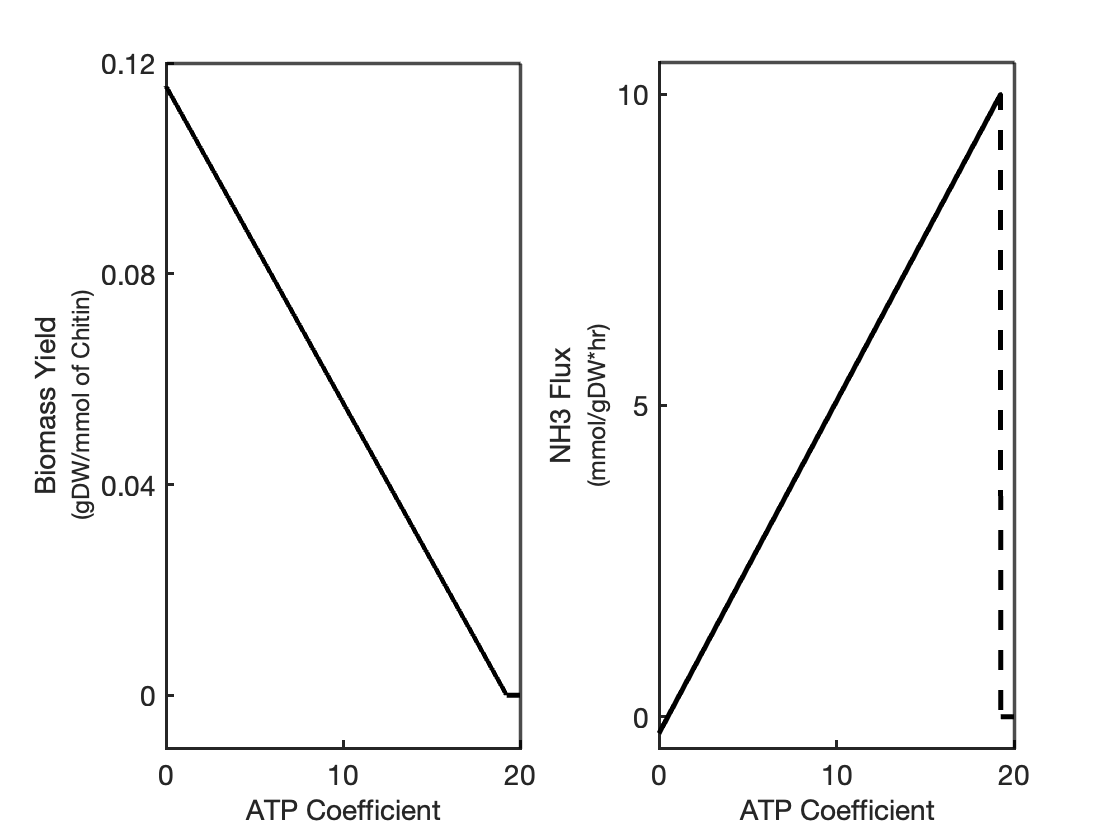

%Figure 1 -- ATP coefficient vs Biomass Yield & ATP coefficient vs NH3 Flux

clf
subplot(1,2,1)
x = 0:0.01:20;

plot(x,biomassValsCJ(1:2001),'LineWidth',2.5,'Color','k');
hold on;
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
ylim([-0.01 0.12])
yticks([0, 0.04 0.08 0.12])
xticks([0 10 20])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}Biomass Yield';'\fontsize{12}(gDW/mmol of Chitin)'}, 'FontSize', 14);
hold off


subplot(1,2,2)

plot(x,NH3ValsCJ(1:2001),'LineWidth',2.5,'Color','k','LineStyle','--');
hold on;

NH3Vals3Diff = NH3ValsCJ;
tol = 1;
yyDiffs  = diff(NH3Vals3Diff);
yyDiffs = [0; yyDiffs;]; %make same length as yy in lazy way
diffintolIndices = abs(yyDiffs) <tol;
x(~diffintolIndices)=NaN;
NH3Vals3Diff(~diffintolIndices)=NaN;

plot(x,NH3Vals3Diff(1:2001),'LineWidth',2.5,'Color','k','LineStyle','-');
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
xticks([0 10 20])
ylim([-0.5 10.5])
yticks([0 5 10])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}NH3 Flux';'\fontsize{12}(mmol/gDW*hr)'});
hold off

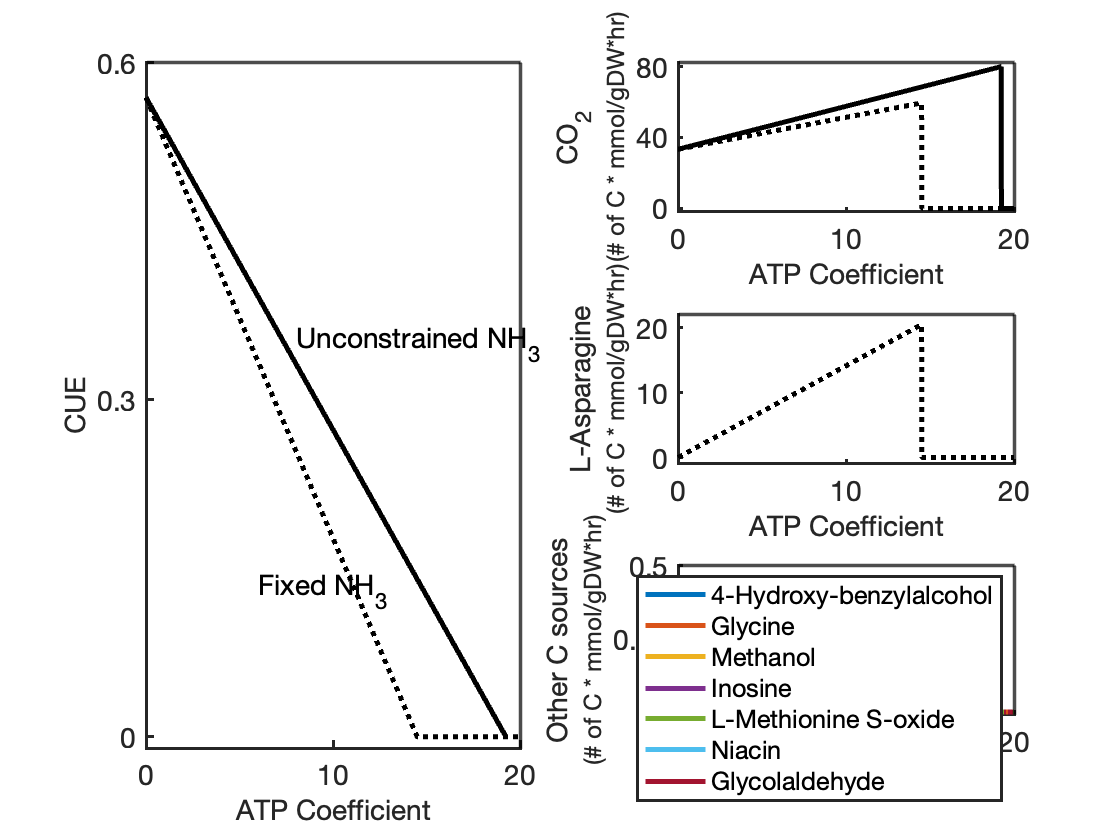

%Figure 2a -- ATP coefficeint vs CUE & the carbon fluxes during that change

clf
subplot(3,2,[1 3 5])
x = 0:0.01:20;

plot(x,CUEvalsCJ(1:2001),'LineWidth',2.5,'Color','k','LineStyle','-')
hold on;
set(gcf,'color','white')    
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
plot(x,CUEvals2(1:2001),'LineWidth',2.5,'Color','k','LineStyle',':')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel('CUE', 'FontSize', 14);
ylim([-0.01 0.6])
yticks([0 0.3 0.6])
xticks([0 10 20])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
text(8,0.35,'Unconstrained NH_3','FontSize',14)
text(6,0.13,'{Fixed NH_3}','FontSize',14)
hold off

carbonCPD = eraseBetween(cTerms,1,3);
carbonCPD(~contains(carbonCPD,"_e0")) = [];
cFlux2 = cFlux2(contains(carbonCPD,"_e0"),:);


idx = cFlux2(:,1) > 0 & cFlux2(:,1) <= 1;
idx2 = cFlux2(:,1) > 1;
idx5 = cFlux2(:,1) == 0 & cFlux2(:,1000) > 1;


carbonMets = cell(length(carbonCPD),1);
for i = 1:length(carbonCPD)
    carbonMets(i) = model.metNames(find(contains(model.mets,carbonCPD(i))));
    if contains(carbonMets(i),"_")
        carbonMets(i) = extractBefore(carbonMets(i),"_");
    end
end

carbonCPD2 = eraseBetween(cTerms2,1,3);
carbonCPD2(~contains(carbonCPD2,"_e0")) = [];
cFlux2 = cFlux2(contains(carbonCPD2,"_e0"),:);

idx3 = cFlux2(:,1) > 0 & cFlux2(:,1) <= 1;
idx4 = cFlux2(:,1) > 1;
idx6 = cFlux2(:,1) == 0 & cFlux2(:,1000) > 1;

carbonMets2 = cell(length(carbonCPD2),1);
for i = 1:length(carbonCPD2)
    carbonMets2(i) = model.metNames(find(contains(model.mets,carbonCPD2(i))));
    if contains(carbonMets2(i),"_")
        carbonMets2(i) = extractBefore(carbonMets2(i),"_");
    end
end


subplot(3,2,2)
x = 0:0.01:20;
plot(x,cFluxCJ(idx2,1:2001),'LineWidth',2.5,'LineStyle','-','Color','k');
hold on; 
set(gca,'ColorOrderIndex',1)
plot(x,cFlux2(idx4,:),'LineWidth',2.5,'LineStyle',':','Color','k')

set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
xticks([0 10 20])
ylim([-2 82])
yticks([0 40 80])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}CO_2';'\fontsize{12}(# of C * mmol/gDW*hr)'}, 'FontSize', 14);
carbonMetsCombined = [carbonMets2(idx4);carbonMets2(idx6)];
hold off


subplot(3,2,4)
x = 0:0.01:20;
plot(x,cFlux2(idx6,:),'LineWidth',2.5,'LineStyle',':','Color','k')
hold on;
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
xticks([0 10 20])
ylim([-1 22])
yticks([0 10 20])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}L-Asparagine';'\fontsize{12}(# of C * mmol/gDW*hr)'}, 'FontSize', 14);
hold off


subplot(3,2,6)
x = 0:0.01:20;
p1 = plot(x,cFluxCJ(idx,1:2001),'LineWidth',2.5);
hold on;
set(gca,'ColorOrderIndex',1)
plot(x,cFlux2(idx3,1:2001),'LineWidth',2.5,'LineStyle',':')
    
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
xticks([0 10 20])
ylim([-0.01 0.5])
yticks([0 0.25 0.5])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}Other C sources';'\fontsize{12}(# of C * mmol/gDW*hr)'}, 'FontSize', 14);
legend(p1,carbonMets2(idx3),'Location','northeast')

hold off

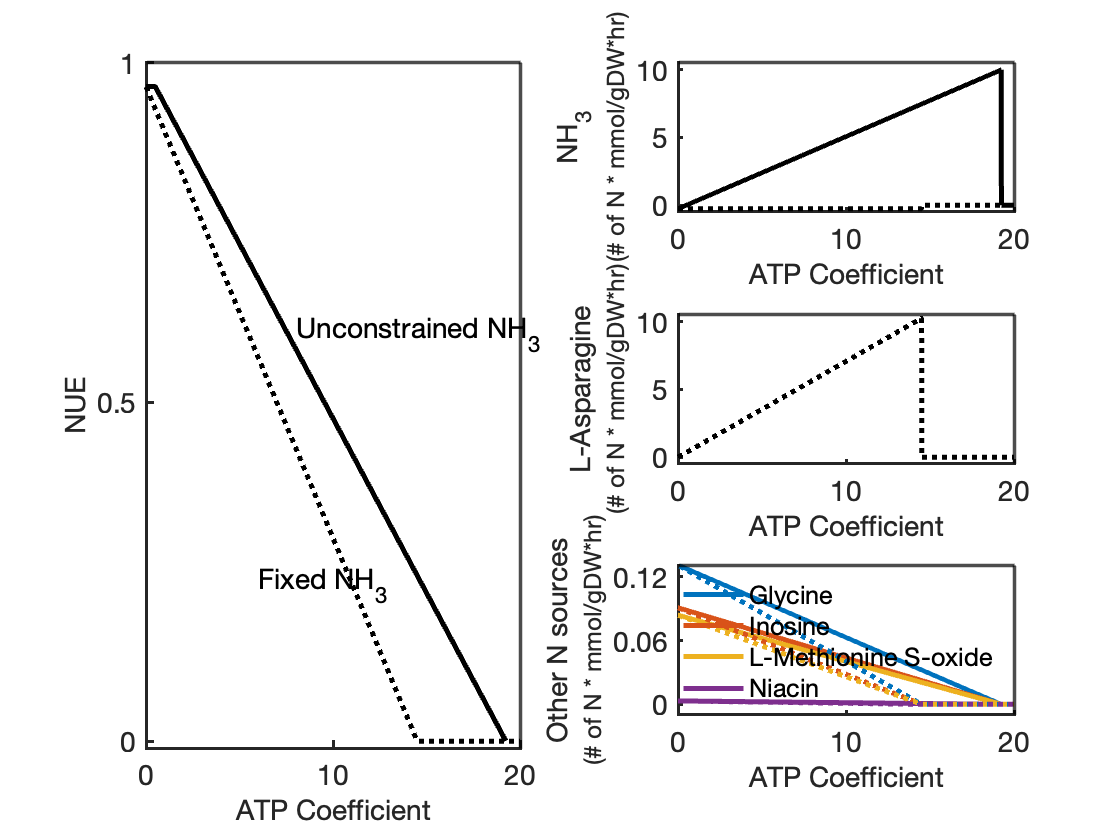


%Figure 2b -- ATP coefficeint vs NUE & the nitrogen fluxes during that change
clf

subplot(3,2,[1 3 5])
x = 0:0.01:20;
plot(x,NUEvalsCJ(1:2001),'LineWidth',2.5,'Color','k','LineStyle','-')
hold on;        
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
plot(x,NUEvals2,'LineWidth',2.5,'Color','k','LineStyle',':');

xticks([0 10 20])
ylim([-0.01 1])
yticks([0 0.5 1])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
text(8,0.6,'Unconstrained NH_3','FontSize',14)
text(6,0.23,'{Fixed NH_3}','FontSize',14)
xlabel('ATP Coefficient', 'FontSize', 14)
ylabel('NUE', 'FontSize', 14);
hold off



nitrogenCPD = eraseBetween(nTerms,1,3);
nitrogenCPD(~contains(nitrogenCPD,"_e0")) = [];
nFlux2 = nFlux2(contains(nitrogenCPD,"_e0"),:);

idx = nFlux2(:,1) > 0 & nFlux2(:,1) <= 1;
idx2 = nFlux2(:,1) < 0 & nFlux2(:,1) >= -1;
idx5 = nFlux2(:,1000) > 1;

nitrogenMets = cell(length(nitrogenCPD),1);
for i = 1:length(nitrogenCPD)
    nitrogenMets(i) = model.metNames(find(contains(model.mets,nitrogenCPD(i))));
    if contains(nitrogenMets(i),"_")
        nitrogenMets(i) = extractBefore(nitrogenMets(i),"_");
    end
end

nitrogenCPD2 = eraseBetween(nTerms2,1,3);
nitrogenCPD2(~contains(nitrogenCPD2,"_e0")) = [];
nFlux2 = nFlux2(contains(nitrogenCPD2,"_e0"),:);

idx3 = nFlux2(:,1) > 0 & nFlux2(:,1) <= 1;
idx4 = nFlux2(:,1) < 0 & nFlux2(:,1) >= -1;
idx6 = nFlux2(:,1000) > 1;

nitrogenMets2 = cell(length(nitrogenCPD2),1);
for i = 1:length(nitrogenCPD2)
    nitrogenMets2(i) = model.metNames(find(contains(model.mets,nitrogenCPD(i))));
    if contains(nitrogenMets2(i),"_")
        nitrogenMets2(i) = extractBefore(nitrogenMets2(i),"_");
    end
end


subplot(3,2,2)
x = 0:0.01:20;
plot(x,nFluxCJ(idx2,1:2001),'LineWidth',2.5,'LineStyle','-','Color','k');
hold on;        
plot(x,nFlux2(idx4,:),'LineWidth',2.5,'LineStyle',':','Color','k');

set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
xticks([0 10 20])
ylim([-0.5 10.5])
yticks([0 5 10])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}NH_3';'\fontsize{12}(# of N * mmol/gDW*hr)'}, 'FontSize', 14);
hold off


subplot(3,2,4)
x = 0:0.01:20;
plot(x,nFlux2(idx6,:),'LineWidth',2.5,'LineStyle',':','Color','k')
hold on;  
     
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
xticks([0 10 20])
ylim([-0.5 10.5])
yticks([0 5 10])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}L-Asparagine';'\fontsize{12}(# of N * mmol/gDW*hr)'}, 'FontSize', 14);
hold off


subplot(3,2,6)
x = 0:0.01:20;
p1 = plot(x,nFluxCJ(idx,1:2001),'LineWidth',2.5);
hold on;  
set(gca,'ColorOrderIndex',1)
plot(x,nFlux2(idx3,1:2001),'LineWidth',2.5,'LineStyle',':')
    
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
xticks([0 10 20])
ylim([-0.01 0.13])
yticks([0 0.06 0.12])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}Other N sources';'\fontsize{12}(# of N * mmol/gDW*hr)'}, 'FontSize', 14);
legend(p1,nitrogenMets2(idx3),'Location','northeast')
legend('boxoff')
hold off

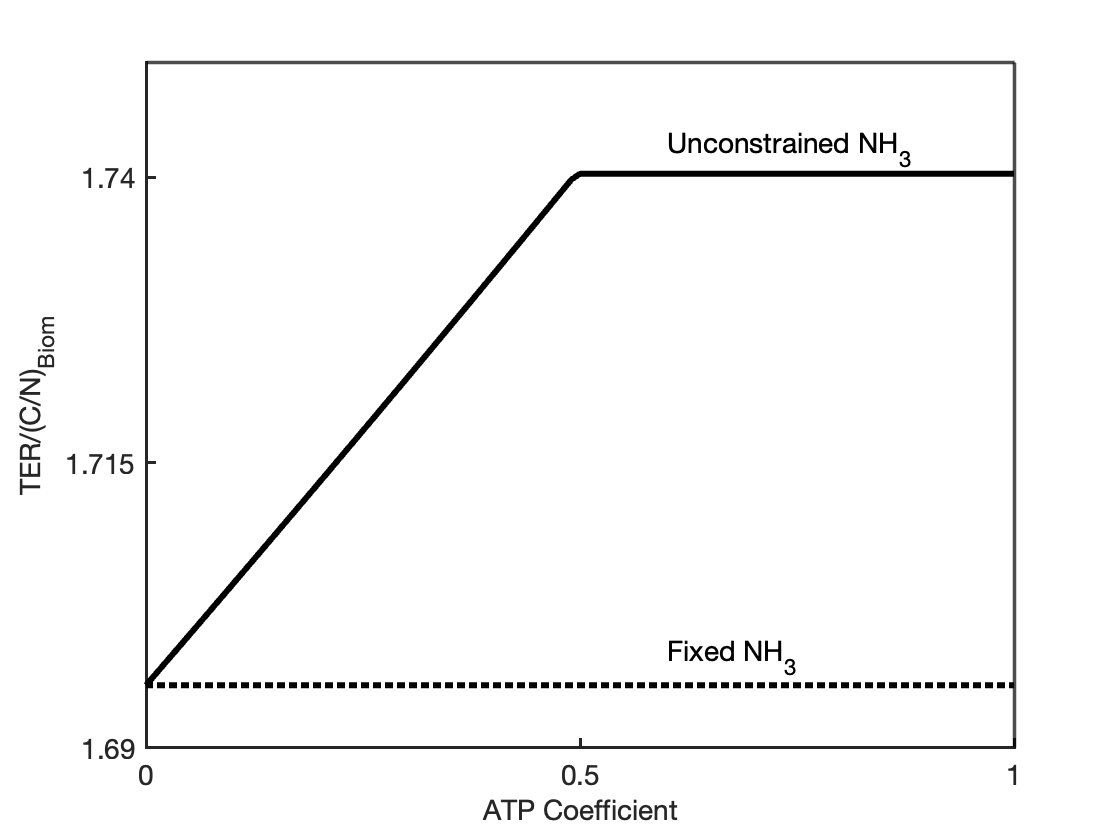


%Figure 3 -- ATP coefficeint vs TER
clf
TERvals2Diff = TERvals2;
x = 0:0.01:20;

tol = 0.1;
yyDiffs  = diff(TERvals2Diff);
yyDiffs = [0; yyDiffs;]; %make same length as yy in lazy way
diffintolIndices = abs(yyDiffs) <tol;
x(~diffintolIndices)=NaN;
TERvals2Diff(~diffintolIndices)=NaN;

TERvals4 = TERvals2(1:1450)';

plot(x,TERvalsCJ(1:2001),'LineWidth',3,'Color','k','LineStyle','-')
hold on;        
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14,'box','off')
plot(0:0.01:14.49,TERvals4,'LineWidth',3,'Color','k','LineStyle',':')
xlim([0 1])
xticks([0 0.5 1])
ylim([1.69 1.75])
yticks([1.69 1.715 1.74])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel('TER/(C/N)_B_i_o_m', 'FontSize', 14);
text(0.6,1.7425,'Unconstrained NH_3','FontSize',14)
text(0.6,1.698,'{Fixed NH_3}','FontSize',14)
hold off

**Part 4. Extracellular metabolites as compared between the 4 models**

%----------------------Values to Change-----------------------------------

MATmodel = 'Cjaponicus0_Model.mat';

%Possible carbon source reactions:
chitinExRxn = 'EX_cpd11683_e0';
nagExRxn = 'EX_cpd00122_e0';
CO2ExRxn = 'EX_cpd00011_e0'; %Necessary to make sure it is set to no consumption.
NH3ExRxn = 'EX_cpd00013_e0';

mediaRxns = {'EX_cpd00001_e0';'EX_cpd00007_e0';'EX_cpd00009_e0';'EX_cpd00011_e0';'EX_cpd00013_e0';...
    'EX_cpd00030_e0';'EX_cpd00034_e0';'EX_cpd00048_e0';'EX_cpd00058_e0';'EX_cpd00063_e0';...
    'EX_cpd00067_e0';'EX_cpd00099_e0';'EX_cpd00122_e0';'EX_cpd00149_e0';'EX_cpd00205_e0';'EX_cpd00244_e0';...
    'EX_cpd00254_e0';'EX_cpd00635_e0';'EX_cpd00971_e0';'EX_cpd03387_e0';'EX_cpd03396_e0';...
    'EX_cpd10515_e0';'EX_cpd10516_e0';'EX_cpd11574_e0';'EX_cpd11683_e0';'EX_cpd15574_e0'};

%Biomass reaction:
biomRxn = 'bio1';

%LBs & UBs of above reactions:
chitinLB = -10;
nagLB = 0;
CO2LB = 0;
mediaLB = -1000;
%-------------------------------------------------------------------------

load(MATmodel)

%Carbon source reaction indeces:
idxChitinRxn = strcmp(model.rxns,chitinExRxn);
idxNAGRxn = strcmp(model.rxns,nagExRxn);

%NH3 reaction index:
idxNH3Rxn = strcmp(model.rxns,NH3ExRxn);

%Biomass reaction index:
idxBiom = find(strcmp(model.rxns,biomRxn));

%Fix upper and lower bounds of media:
idxExRxns = find(contains(model.rxns,'EX_'));
model.lb(idxExRxns) = 0;
model.ub(idxExRxns) = 1000;

for i = 1:length(mediaRxns)
    idxMediaRxn = find(strcmp(model.rxns,mediaRxns(i)));
    model.lb(idxMediaRxn) = mediaLB;
end

%Make sure CO2 remains 0 (unnecessary but just to be sure)
idxCO2Rxn = find(strcmp(model.rxns,CO2ExRxn));
model.lb(idxCO2Rxn) = CO2LB;
  
%Set Inequalities, equality and LBs & UBs:
Aeqlb = model.lb;
Aeqlb(idxChitinRxn) = chitinLB;
Aeqlb(idxNAGRxn) = nagLB;

Aequb = model.ub;

Aeq = model.S;
beq = zeros(size(Aeq,1),1);

%Inequality reactions -- empty sets
Aineq = []; bineq = [];


%Build Gurobi model on binary growth        
modelSolve.A = sparse([Aineq; Aeq]);
modelSolve.rhs = [bineq; beq];
modelSolve.lb = Aeqlb;
modelSolve.ub = Aequb;
modelSolve.sense = [repmat('<',1,size(Aineq,1)) repmat('=',1,size(Aeq,1))];

f = zeros(1,size(Aeq,2));
f(idxBiom) = 1;

modelSolve.obj = f;
modelSolve.modelsense = 'max';
params.outputflag = 0;
result = gurobi(modelSolve,params); 
biomass = result.objval
%Now to perform pFBA:
[m,n] = size(model.S);
IrrevPosRxns = zeros(n,1);
IrrevNegRxns = zeros(n,1);
RevRxns = zeros(n,1);

for i = 1:n
    if Aeqlb(i) < 0 && Aequb(i) > 0
        RevRxns(i) = 1;
    elseif Aeqlb(i) < 0 && Aequb(i) == 0
        IrrevNegRxns(i) = 1;
    elseif Aeqlb(i) == 0 && Aequb(i) > 0
        IrrevPosRxns(i) = 1;
    end
end

pAineqPRxns1 = zeros(n,2*n);
pAineqPRxns2 = zeros(n,2*n);
for j = 1:n    
    if IrrevPosRxns(j) == 1
        pAineqPRxns1(j,j) = -1;
        pAineqPRxns2(j,j) = 1;
        pAineqPRxns2(j,n+j) = -1;
    end
end
pAineqPRxns1 = pAineqPRxns1(any(pAineqPRxns1,2),:);
pAineqPRxns2 = pAineqPRxns2(any(pAineqPRxns2,2),:);

pAineqNRxns1 = zeros(n,2*n);
pAineqNRxns2 = zeros(n,2*n);
for j = 1:n    
    if IrrevNegRxns(j) == 1
        pAineqNRxns1(j,j) = 1;
        pAineqNRxns2(j,j) = -1;
        pAineqNRxns2(j,n+j) = -1;
    end
end
pAineqNRxns1 = pAineqNRxns1(any(pAineqNRxns1,2),:);
pAineqNRxns2 = pAineqNRxns2(any(pAineqNRxns2,2),:);

pAineqRRxns1 = zeros(n,2*n);
pAineqRRxns2 = zeros(n,2*n);
for j = 1:n    
    if RevRxns(j) == 1
        pAineqRRxns1(j,j) = -1;
        pAineqRRxns1(j,n+j) = -1;
        pAineqRRxns2(j,j) = 1;
        pAineqRRxns2(j,n+j) = -1;
    end
end
pAineqRRxns1 = pAineqRRxns1(any(pAineqRRxns1,2),:);
pAineqRRxns2 = pAineqRRxns2(any(pAineqRRxns2,2),:);

pAineq = [pAineqPRxns1; pAineqPRxns2; pAineqNRxns1; pAineqNRxns2; pAineqRRxns1; pAineqRRxns2];
pbineq = zeros(size(pAineq,1),1);

pAeq = [model.S zeros(m,n)];
pbeq = zeros(size(pAeq,1),1);

modelP.A = sparse([pAineq; pAeq]);
modelP.rhs = [pbineq; pbeq];
modelP.sense = [repmat('<',1,size(pAineq,1)) repmat('=',1,size(pAeq,1))];

modelP.lb = [Aeqlb; zeros(n,1)];
modelP.ub = [Aequb; 1000*ones(n,1)];
modelP.lb(idxBiom) = biomass;
modelP.ub(idxBiom) = biomass;

f = [zeros(1,n) ones(1,n)];
modelP.obj = f;
modelP.modelsense = 'min';

params.outputflag = 0;
resultP = gurobi(modelP,params);

resultP.objval
NH3Bound = resultP.x(idxNH3Rxn);
NH3Bound
%Find extracellular fluxes and names

ExRxnNames = erase(model.rxnNames(idxExRxns),'Exchange for');
ExRxnNames = erase(ExRxnNames,'_e0'); %Shortening length of extracellular reaction name

for i = 1:length(resultP.x)
    if abs(resultP.x(i))<1e-5
    resultP.x(i)=0;
    end
end

pTable0 = table(model.rxns(idxExRxns),ExRxnNames,resultP.x(idxExRxns),'VariableNames',{'ModelSEED ID','Rxn Names','pFlux'});
pTable0(~pTable0.pFlux,:) = [];
pTable0 = sortrows(pTable0,'pFlux')
%Bar graph:

y = sign(pTable0.pFlux).*log10(1+abs(pTable0.pFlux)/10^-3);

figure
ax1 = gca();
hold on
box on
set(gcf,'color','w');

ax1.LineWidth = 1.5;
bar(y)
set(ax1,'XTick',1:length(pTable0.pFlux),'XTickLabel',pTable0.("Rxn Names"),'FontSize',14,'fontweight','bold');
xlabel('Metabolites','FontSize',20)
yyaxis left
yticks([-5 -4 -3 -2 -1 0 1 2 3 4 5])
yticklabels({'-100','-10','-1','-0.1','-0.01','0','0.01','0.1','1','10','100'})
ylabel('log_1_0Flux (mmol gDW^-^1 hr^-^1)','FontSize',20)
yyaxis right
yticks([0.25 0.75])
yticklabels({'Consumed','Produced'})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
hold off

%----------------------Values to Change-----------------------------------

MATmodel = 'Cjaponicus10_Model.mat';

%Possible carbon source reactions:
chitinExRxn = 'EX_cpd11683_e0';
nagExRxn = 'EX_cpd00122_e0';
CO2ExRxn = 'EX_cpd00011_e0'; %Necessary to make sure it is set to no consumption.

mediaRxns = {'EX_cpd00001_e0';'EX_cpd00007_e0';'EX_cpd00009_e0';'EX_cpd00011_e0';'EX_cpd00013_e0';...
    'EX_cpd00030_e0';'EX_cpd00034_e0';'EX_cpd00048_e0';'EX_cpd00058_e0';'EX_cpd00063_e0';...
    'EX_cpd00067_e0';'EX_cpd00099_e0';'EX_cpd00122_e0';'EX_cpd00149_e0';'EX_cpd00205_e0';'EX_cpd00244_e0';...
    'EX_cpd00254_e0';'EX_cpd00635_e0';'EX_cpd00971_e0';'EX_cpd03387_e0';'EX_cpd03396_e0';...
    'EX_cpd10515_e0';'EX_cpd10516_e0';'EX_cpd11574_e0';'EX_cpd11683_e0';'EX_cpd15574_e0'};

%Biomass reaction:
biomRxn = 'bio1';

%LBs & UBs of above reactions:
chitinLB = -10;
nagLB = 0;
CO2LB = 0;
mediaLB = -1000;
%-------------------------------------------------------------------------

load(MATmodel)

%Carbon source reaction indeces:
idxChitinRxn = strcmp(model.rxns,chitinExRxn);
idxNAGRxn = strcmp(model.rxns,nagExRxn);

%Biomass reaction index:
idxBiom = find(strcmp(model.rxns,biomRxn));

%Fix upper and lower bounds of media:
idxExRxns = find(contains(model.rxns,'EX_'));
model.lb(idxExRxns) = 0;
model.ub(idxExRxns) = 1000;

for i = 1:length(mediaRxns)
    idxMediaRxn = find(strcmp(model.rxns,mediaRxns(i)));
    model.lb(idxMediaRxn) = mediaLB;
end

%Make sure CO2 remains 0 (unnecessary but just to be sure)
idxCO2Rxn = find(strcmp(model.rxns,CO2ExRxn));
model.lb(idxCO2Rxn) = CO2LB;
  
%Set Inequalities, equality and LBs & UBs:
Aeqlb = model.lb;
Aeqlb(idxChitinRxn) = chitinLB;
Aeqlb(idxNAGRxn) = nagLB;

Aequb = model.ub;

Aeq = model.S;
beq = zeros(size(Aeq,1),1);

%Inequality reactions -- empty sets
Aineq = []; bineq = [];


%Build Gurobi model on binary growth        
modelSolve.A = sparse([Aineq; Aeq]);
modelSolve.rhs = [bineq; beq];
modelSolve.lb = Aeqlb;
modelSolve.ub = Aequb;
modelSolve.sense = [repmat('<',1,size(Aineq,1)) repmat('=',1,size(Aeq,1))];

f = zeros(1,size(Aeq,2));
f(idxBiom) = 1;

modelSolve.obj = f;
modelSolve.modelsense = 'max';
params.outputflag = 0;
result = gurobi(modelSolve,params); 
biomass = result.objval
%Now to perform pFBA:
[m,n] = size(model.S);
IrrevPosRxns = zeros(n,1);
IrrevNegRxns = zeros(n,1);
RevRxns = zeros(n,1);

for i = 1:n
    if Aeqlb(i) < 0 && Aequb(i) > 0
        RevRxns(i) = 1;
    elseif Aeqlb(i) < 0 && Aequb(i) == 0
        IrrevNegRxns(i) = 1;
    elseif Aeqlb(i) == 0 && Aequb(i) > 0
        IrrevPosRxns(i) = 1;
    end
end

pAineqPRxns1 = zeros(n,2*n);
pAineqPRxns2 = zeros(n,2*n);
for j = 1:n    
    if IrrevPosRxns(j) == 1
        pAineqPRxns1(j,j) = -1;
        pAineqPRxns2(j,j) = 1;
        pAineqPRxns2(j,n+j) = -1;
    end
end
pAineqPRxns1 = pAineqPRxns1(any(pAineqPRxns1,2),:);
pAineqPRxns2 = pAineqPRxns2(any(pAineqPRxns2,2),:);

pAineqNRxns1 = zeros(n,2*n);
pAineqNRxns2 = zeros(n,2*n);
for j = 1:n    
    if IrrevNegRxns(j) == 1
        pAineqNRxns1(j,j) = 1;
        pAineqNRxns2(j,j) = -1;
        pAineqNRxns2(j,n+j) = -1;
    end
end
pAineqNRxns1 = pAineqNRxns1(any(pAineqNRxns1,2),:);
pAineqNRxns2 = pAineqNRxns2(any(pAineqNRxns2,2),:);

pAineqRRxns1 = zeros(n,2*n);
pAineqRRxns2 = zeros(n,2*n);
for j = 1:n    
    if RevRxns(j) == 1
        pAineqRRxns1(j,j) = -1;
        pAineqRRxns1(j,n+j) = -1;
        pAineqRRxns2(j,j) = 1;
        pAineqRRxns2(j,n+j) = -1;
    end
end
pAineqRRxns1 = pAineqRRxns1(any(pAineqRRxns1,2),:);
pAineqRRxns2 = pAineqRRxns2(any(pAineqRRxns2,2),:);

pAineq = [pAineqPRxns1; pAineqPRxns2; pAineqNRxns1; pAineqNRxns2; pAineqRRxns1; pAineqRRxns2];
pbineq = zeros(size(pAineq,1),1);

pAeq = [model.S zeros(m,n)];
pbeq = zeros(size(pAeq,1),1);

modelP.A = sparse([pAineq; pAeq]);
modelP.rhs = [pbineq; pbeq];
modelP.sense = [repmat('<',1,size(pAineq,1)) repmat('=',1,size(pAeq,1))];

modelP.lb = [Aeqlb; zeros(n,1)];
modelP.ub = [Aequb; 1000*ones(n,1)];
modelP.lb(idxBiom) = biomass;
modelP.ub(idxBiom) = biomass;

f = [zeros(1,n) ones(1,n)];
modelP.obj = f;
modelP.modelsense = 'min';

params.outputflag = 0;
resultP = gurobi(modelP,params);

resultP.objval
%Find extracellular fluxes and names

ExRxnNames = erase(model.rxnNames(idxExRxns),'Exchange for');
ExRxnNames = erase(ExRxnNames,'_e0'); %Shortening length of extracellular reaction name

for i = 1:length(resultP.x)
    if abs(resultP.x(i))<1e-5
    resultP.x(i)=0;
    end
end

pTable10 = table(model.rxns(idxExRxns),ExRxnNames,resultP.x(idxExRxns),'VariableNames',{'ModelSEED ID','Rxn Names','pFlux'});
pTable10(~pTable10.pFlux,:) = [];
pTable10 = sortrows(pTable10,'pFlux')
%Bar graph:

y = sign(pTable10.pFlux).*log10(1+abs(pTable10.pFlux)/10^-3);

figure
ax1 = gca();
hold on
box on
set(gcf,'color','w');

ax1.LineWidth = 1.5;
bar(y)
set(ax1,'XTick',1:length(pTable10.pFlux),'XTickLabel',pTable10.("Rxn Names"),'FontSize',14,'fontweight','bold');
xlabel('Metabolites','FontSize',20)
yyaxis left
yticks([-5 -4 -3 -2 -1 0 1 2 3 4 5])
yticklabels({'-100','-10','-1','-0.1','-0.01','0','0.01','0.1','1','10','100'})
ylabel('log_1_0Flux (mmol gDW^-^1 hr^-^1)','FontSize',20)
yyaxis right
yticks([0.25 0.75])
yticklabels({'Consumed','Produced'})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
hold off

%----------------------Values to Change-----------------------------------

MATmodel = 'Cjaponicus25_Model.mat';

%Possible carbon source reactions:
chitinExRxn = 'EX_cpd11683_e0';
nagExRxn = 'EX_cpd00122_e0';
CO2ExRxn = 'EX_cpd00011_e0'; %Necessary to make sure it is set to no consumption.

mediaRxns = {'EX_cpd00001_e0';'EX_cpd00007_e0';'EX_cpd00009_e0';'EX_cpd00011_e0';'EX_cpd00013_e0';...
    'EX_cpd00030_e0';'EX_cpd00034_e0';'EX_cpd00048_e0';'EX_cpd00058_e0';'EX_cpd00063_e0';...
    'EX_cpd00067_e0';'EX_cpd00099_e0';'EX_cpd00122_e0';'EX_cpd00149_e0';'EX_cpd00205_e0';'EX_cpd00244_e0';...
    'EX_cpd00254_e0';'EX_cpd00635_e0';'EX_cpd00971_e0';'EX_cpd03387_e0';'EX_cpd03396_e0';...
    'EX_cpd10515_e0';'EX_cpd10516_e0';'EX_cpd11574_e0';'EX_cpd11683_e0';'EX_cpd15574_e0'};

%Biomass reaction:
biomRxn = 'bio1';

%LBs & UBs of above reactions:
chitinLB = -10;
nagLB = 0;
CO2LB = 0;
mediaLB = -1000;
%-------------------------------------------------------------------------

load(MATmodel)

%Carbon source reaction indeces:
idxChitinRxn = strcmp(model.rxns,chitinExRxn);
idxNAGRxn = strcmp(model.rxns,nagExRxn);

%Biomass reaction index:
idxBiom = find(strcmp(model.rxns,biomRxn));

%Fix upper and lower bounds of media:
idxExRxns = find(contains(model.rxns,'EX_'));
model.lb(idxExRxns) = 0;
model.ub(idxExRxns) = 1000;

for i = 1:length(mediaRxns)
    idxMediaRxn = find(strcmp(model.rxns,mediaRxns(i)));
    model.lb(idxMediaRxn) = mediaLB;
end

%Make sure CO2 remains 0 (unnecessary but just to be sure)
idxCO2Rxn = find(strcmp(model.rxns,CO2ExRxn));
model.lb(idxCO2Rxn) = CO2LB;
  
%Set Inequalities, equality and LBs & UBs:
Aeqlb = model.lb;
Aeqlb(idxChitinRxn) = chitinLB;
Aeqlb(idxNAGRxn) = nagLB;

Aequb = model.ub;

Aeq = model.S;
beq = zeros(size(Aeq,1),1);

%Inequality reactions -- empty sets
Aineq = []; bineq = [];


%Build Gurobi model on binary growth        
modelSolve.A = sparse([Aineq; Aeq]);
modelSolve.rhs = [bineq; beq];
modelSolve.lb = Aeqlb;
modelSolve.ub = Aequb;
modelSolve.sense = [repmat('<',1,size(Aineq,1)) repmat('=',1,size(Aeq,1))];

f = zeros(1,size(Aeq,2));
f(idxBiom) = 1;

modelSolve.obj = f;
modelSolve.modelsense = 'max';
params.outputflag = 0;
result = gurobi(modelSolve,params); 
biomass = result.objval
%Now to perform pFBA:
[m,n] = size(model.S);
IrrevPosRxns = zeros(n,1);
IrrevNegRxns = zeros(n,1);
RevRxns = zeros(n,1);

for i = 1:n
    if Aeqlb(i) < 0 && Aequb(i) > 0
        RevRxns(i) = 1;
    elseif Aeqlb(i) < 0 && Aequb(i) == 0
        IrrevNegRxns(i) = 1;
    elseif Aeqlb(i) == 0 && Aequb(i) > 0
        IrrevPosRxns(i) = 1;
    end
end

pAineqPRxns1 = zeros(n,2*n);
pAineqPRxns2 = zeros(n,2*n);
for j = 1:n    
    if IrrevPosRxns(j) == 1
        pAineqPRxns1(j,j) = -1;
        pAineqPRxns2(j,j) = 1;
        pAineqPRxns2(j,n+j) = -1;
    end
end
pAineqPRxns1 = pAineqPRxns1(any(pAineqPRxns1,2),:);
pAineqPRxns2 = pAineqPRxns2(any(pAineqPRxns2,2),:);

pAineqNRxns1 = zeros(n,2*n);
pAineqNRxns2 = zeros(n,2*n);
for j = 1:n    
    if IrrevNegRxns(j) == 1
        pAineqNRxns1(j,j) = 1;
        pAineqNRxns2(j,j) = -1;
        pAineqNRxns2(j,n+j) = -1;
    end
end
pAineqNRxns1 = pAineqNRxns1(any(pAineqNRxns1,2),:);
pAineqNRxns2 = pAineqNRxns2(any(pAineqNRxns2,2),:);

pAineqRRxns1 = zeros(n,2*n);
pAineqRRxns2 = zeros(n,2*n);
for j = 1:n    
    if RevRxns(j) == 1
        pAineqRRxns1(j,j) = -1;
        pAineqRRxns1(j,n+j) = -1;
        pAineqRRxns2(j,j) = 1;
        pAineqRRxns2(j,n+j) = -1;
    end
end
pAineqRRxns1 = pAineqRRxns1(any(pAineqRRxns1,2),:);
pAineqRRxns2 = pAineqRRxns2(any(pAineqRRxns2,2),:);

pAineq = [pAineqPRxns1; pAineqPRxns2; pAineqNRxns1; pAineqNRxns2; pAineqRRxns1; pAineqRRxns2];
pbineq = zeros(size(pAineq,1),1);

pAeq = [model.S zeros(m,n)];
pbeq = zeros(size(pAeq,1),1);

modelP.A = sparse([pAineq; pAeq]);
modelP.rhs = [pbineq; pbeq];
modelP.sense = [repmat('<',1,size(pAineq,1)) repmat('=',1,size(pAeq,1))];

modelP.lb = [Aeqlb; zeros(n,1)];
modelP.ub = [Aequb; 1000*ones(n,1)];
modelP.lb(idxBiom) = biomass;
modelP.ub(idxBiom) = biomass;

f = [zeros(1,n) ones(1,n)];
modelP.obj = f;
modelP.modelsense = 'min';

params.outputflag = 0;
resultP = gurobi(modelP,params);

resultP.objval
%Find extracellular fluxes and names

ExRxnNames = erase(model.rxnNames(idxExRxns),'Exchange for');
ExRxnNames = erase(ExRxnNames,'_e0'); %Shortening length of extracellular reaction name

for i = 1:length(resultP.x)
    if abs(resultP.x(i))<1e-5
    resultP.x(i)=0;
    end
end

pTable25 = table(model.rxns(idxExRxns),ExRxnNames,resultP.x(idxExRxns),'VariableNames',{'ModelSEED ID','Rxn Names','pFlux'});
pTable25(~pTable25.pFlux,:) = [];
pTable25 = sortrows(pTable25,'pFlux')
%Bar graph:

y = sign(pTable25.pFlux).*log10(1+abs(pTable25.pFlux)/10^-3);

figure
ax1 = gca();
hold on
box on
set(gcf,'color','w');

ax1.LineWidth = 1.5;
bar(y)
set(ax1,'XTick',1:length(pTable25.pFlux),'XTickLabel',pTable25.("Rxn Names"),'FontSize',14,'fontweight','bold');
xlabel('Metabolites','FontSize',20)
yyaxis left
yticks([-5 -4 -3 -2 -1 0 1 2 3 4 5])
yticklabels({'-100','-10','-1','-0.1','-0.01','0','0.01','0.1','1','10','100'})
ylabel('log_1_0Flux (mmol gDW^-^1 hr^-^1)','FontSize',20)
yyaxis right
yticks([0.25 0.75])
yticklabels({'Consumed','Produced'})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
hold off

%----------------------Values to Change-----------------------------------

MATmodel = 'Cjaponicus50_Model.mat';

%Possible carbon source reactions:
chitinExRxn = 'EX_cpd11683_e0';
nagExRxn = 'EX_cpd00122_e0';
CO2ExRxn = 'EX_cpd00011_e0'; %Necessary to make sure it is set to no consumption.

mediaRxns = {'EX_cpd00001_e0';'EX_cpd00007_e0';'EX_cpd00009_e0';'EX_cpd00011_e0';'EX_cpd00013_e0';...
    'EX_cpd00030_e0';'EX_cpd00034_e0';'EX_cpd00048_e0';'EX_cpd00058_e0';'EX_cpd00063_e0';...
    'EX_cpd00067_e0';'EX_cpd00099_e0';'EX_cpd00122_e0';'EX_cpd00149_e0';'EX_cpd00205_e0';'EX_cpd00244_e0';...
    'EX_cpd00254_e0';'EX_cpd00635_e0';'EX_cpd00971_e0';'EX_cpd03387_e0';'EX_cpd03396_e0';...
    'EX_cpd10515_e0';'EX_cpd10516_e0';'EX_cpd11574_e0';'EX_cpd11683_e0';'EX_cpd15574_e0'};

%Biomass reaction:
biomRxn = 'bio1';

%LBs & UBs of above reactions:
chitinLB = -10;
nagLB = 0;
CO2LB = 0;
mediaLB = -1000;
%-------------------------------------------------------------------------

load(MATmodel)

%Carbon source reaction indeces:
idxChitinRxn = strcmp(model.rxns,chitinExRxn);
idxNAGRxn = strcmp(model.rxns,nagExRxn);

%Biomass reaction index:
idxBiom = find(strcmp(model.rxns,biomRxn));

%Fix upper and lower bounds of media:
idxExRxns = find(contains(model.rxns,'EX_'));
model.lb(idxExRxns) = 0;
model.ub(idxExRxns) = 1000;

for i = 1:length(mediaRxns)
    idxMediaRxn = find(strcmp(model.rxns,mediaRxns(i)));
    model.lb(idxMediaRxn) = mediaLB;
end

%Make sure CO2 remains 0 (unnecessary but just to be sure)
idxCO2Rxn = find(strcmp(model.rxns,CO2ExRxn));
model.lb(idxCO2Rxn) = CO2LB;
  
%Set Inequalities, equality and LBs & UBs:
Aeqlb = model.lb;
Aeqlb(idxChitinRxn) = chitinLB;
Aeqlb(idxNAGRxn) = nagLB;

Aequb = model.ub;

Aeq = model.S;
beq = zeros(size(Aeq,1),1);

%Inequality reactions -- empty sets
Aineq = []; bineq = [];


%Build Gurobi model on binary growth        
modelSolve.A = sparse([Aineq; Aeq]);
modelSolve.rhs = [bineq; beq];
modelSolve.lb = Aeqlb;
modelSolve.ub = Aequb;
modelSolve.sense = [repmat('<',1,size(Aineq,1)) repmat('=',1,size(Aeq,1))];

f = zeros(1,size(Aeq,2));
f(idxBiom) = 1;

modelSolve.obj = f;
modelSolve.modelsense = 'max';
params.outputflag = 0;
result = gurobi(modelSolve,params); 
biomass = result.objval
 
%Find extracellular fluxes and names

ExRxnNames = erase(model.rxnNames(idxExRxns),'Exchange for');
ExRxnNames = erase(ExRxnNames,'_e0'); %Shortening length of extracellular reaction name

for i = 1:length(resultP.x)
    if abs(resultP.x(i))<1e-5
    resultP.x(i)=0;
    end
end

pTable50 = table(model.rxns(idxExRxns),ExRxnNames,resultP.x(idxExRxns),'VariableNames',{'ModelSEED ID','Rxn Names','pFlux'});
pTable50(~pTable50.pFlux,:) = [];
pTable50 = sortrows(pTable50,'pFlux')
%Bar graph:

y = sign(pTable50.pFlux).*log10(1+abs(pTable50.pFlux)/10^-3);

figure
ax1 = gca();
hold on
box on
set(gcf,'color','w');

ax1.LineWidth = 1.5;
bar(y)
set(ax1,'XTick',1:length(pTable50.pFlux),'XTickLabel',pTable50.("Rxn Names"),'FontSize',14,'fontweight','bold');
xlabel('Metabolites','FontSize',20)
yyaxis left
yticks([-5 -4 -3 -2 -1 0 1 2 3 4 5])
yticklabels({'-100','-10','-1','-0.1','-0.01','0','0.01','0.1','1','10','100'})
ylabel('log_1_0Flux (mmol gDW^-^1 hr^-^1)','FontSize',20)
yyaxis right
yticks([0.25 0.75])
yticklabels({'Consumed','Produced'})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
hold off

combinedTable1 = outerjoin(pTable0,pTable10,'Keys',{'ModelSEED ID','Rxn Names'},'MergeKeys',true);
combinedTable1 = renamevars(combinedTable1,'pFlux_pTable0','Cj0');
combinedTable1 = renamevars(combinedTable1,'pFlux_pTable10','Cj10');

combinedTable2= outerjoin(pTable25,pTable50,'Keys',{'ModelSEED ID','Rxn Names'},'MergeKeys',true);
combinedTable2 = renamevars(combinedTable2,'pFlux_pTable25','Cj25');
combinedTable2 = renamevars(combinedTable2,'pFlux_pTable50','Cj50');


combinedTable = outerjoin(combinedTable1,combinedTable2,'Keys',{'ModelSEED ID','Rxn Names'},'MergeKeys',true);
combinedTable = sortrows(combinedTable,'Cj50')

%Bar graph:

y0 = sign(combinedTable.Cj0).*log10(1+abs(combinedTable.Cj0/10^-3));
y10 = sign(combinedTable.Cj10).*log10(1+abs(combinedTable.Cj10/10^-3));
y25 = sign(combinedTable.Cj25).*log10(1+abs(combinedTable.Cj25/10^-3));
y50 = sign(combinedTable.Cj50).*log10(1+abs(combinedTable.Cj50/10^-3));

figure
ax1 = gca();
hold on
box on
set(gcf,'color','w');
ax1.LineWidth = 1.5;
bar([y0 y10 y25 y50])
set(ax1,'XTick',1:length(combinedTable.("Rxn Names")),'XTickLabel',combinedTable.("Rxn Names"),'FontSize',14,'box','off');
xlabel('Metabolites','FontSize',16)
ylim([-5 5])
yline(max(ylim),'LineWidth',1.75,'Color','black')
yyaxis left
ylabel({'\fontsize{16}Flux';'\fontsize{14}(mmol/gDW*hr)'});
yticks([-4 -3 -2 -1 0 1 2 3 4 ])
yticklabels({'-10','-1','-0.1','-0.01','0','0.01','0.1','1','10'})
yyaxis right
yticks([0.25 0.75])
yticklabels({'Consumed','Produced'})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
lgd = legend('0% (ATP coeff = 0)','10% (ATP coeff = 1.93)','25% (ATP coeff = 4.81)','50% (ATP coeff = 9.62)'); 
legend('boxoff')
title(lgd,'Decrease in biomass yield:') 
hold off